## Fixed point iteration

Numerical methods allow us to solve complex mathematical problems that the usual pen and paper would struggle with. While algebra, calculus and analysis might provide us with exact answers, NM give us an inexact approach to such solutions, broken up in often simple (but numerous) mathematical operations. Inexact may appear to be an undesirable outcome in any kind of problem solving, but the hundredth decimal goes unnoticed if our hardware or tolerance is not capable of computing it.

The fixed-point iteration method calculates roots of functions using a "fixed point". Our function must be algebraically transformed to satisfy the fixed point condition.

### F(x)=0  x=g(x) 

We will use 

### f(x)=cos(x)-x 

as an example function. We must algebraically transform it to the form x=g(x)

## x=cos(x) 

The method is implemented as it follows:

function raiz=fixedpoint(F,x1,t,i,p)
 % F en funcion x=g(x)
 % x1 primer valor
 % t tolerancia ahora si implementada :)))))
 % i iteraciones
 % p 0=Raiz en texto, 1=plots de error y valor

    fx=F;                       %llama funcion
    v=0;                        %inicia el loop counte 
    ee=t;                       %cambio de nombre de funcion
    ie=100;                     %define el error inicial en 100%

Using MatLab Functions we declare the fixed Point method with the function to be solved, first guess, tolerance, iterations, and a :p" flag to output plots or hard values

     while v < i  && ie >= ee        %Condicion menor que iteraciones o mayor que tolerancia

        x2=fx(x1);                  %evalua en primer punto
        groots(v+1)=x2;             %array de iteraciones de x
        
        v=v+1                       %counter sum
        disp('Error act: ')
        disp((((abs((x1-x2)))/x1)*100))  %muestra valor actual de error
        ie=((abs((x1-x2)))/x1)*100;      %calcula error de elemento actual vs pasado
        x1=x2 ;                     %valor actual


    end

A while loop with iteration and tolerance level as conditionals. The loop evaluates the function in the first guess(x1) and writes that data in an array. Calculates the error and passes the value to the loop conditional. Finally it passes the evaluated value(x2) to x1, evaluating the second number in the next pass of the function loop.

    e=1; %counter de loop error
     %%errs = zeros(1,i);
    while e<v           %loop de matriz de errores
     errs(e) = ((abs((groots(v)-groots(e+1))))/groots(v))*100; %calcula el errores de cada elemento del array vs el final
     e=e+1;
    end

This while loop calculates error versus the final value (absolute) to each 'guess' in the array, passing the value to another array.

    if (p==true)          %graficos de error y valor si p=1
        subplot(2,1,1);
        plot(errs,LineWidth=2,Color=[1 0 0])
        title('Porcentaje de error')
        xlabel('iteraciones')
        ylabel('% error')
        

        subplot(2,1,2);
        plot(groots,LineWidth=2)
        title('Estimado de solucion')
        xlabel('iteraciones')
        ylabel('valor')
        yline(groots(v),Color=[0.9290 0.6940 0.1250],LineWidth=1.5,LineStyle="--") %linea de valor final
        
        


    else
        disp(" ")
        disp(" ")
        disp("Resultados")
        disp(" ")
        disp("Raiz: ")    %resultado final si p =0
        disp(groots(v))
        disp("Iteraciones:")
        disp(v)
    end

    
   raiz=groots(v);  %pasa valor de funcion

end

Finally (as an analysis tool) the flag p in the function runs and outputs a plot of values vs iterations(Blue) and aprox error of each item in the array (Red). Notice how the roots cicle betweent values and stabilize after 16 or so iterations. The error aproximates 0 at the same values

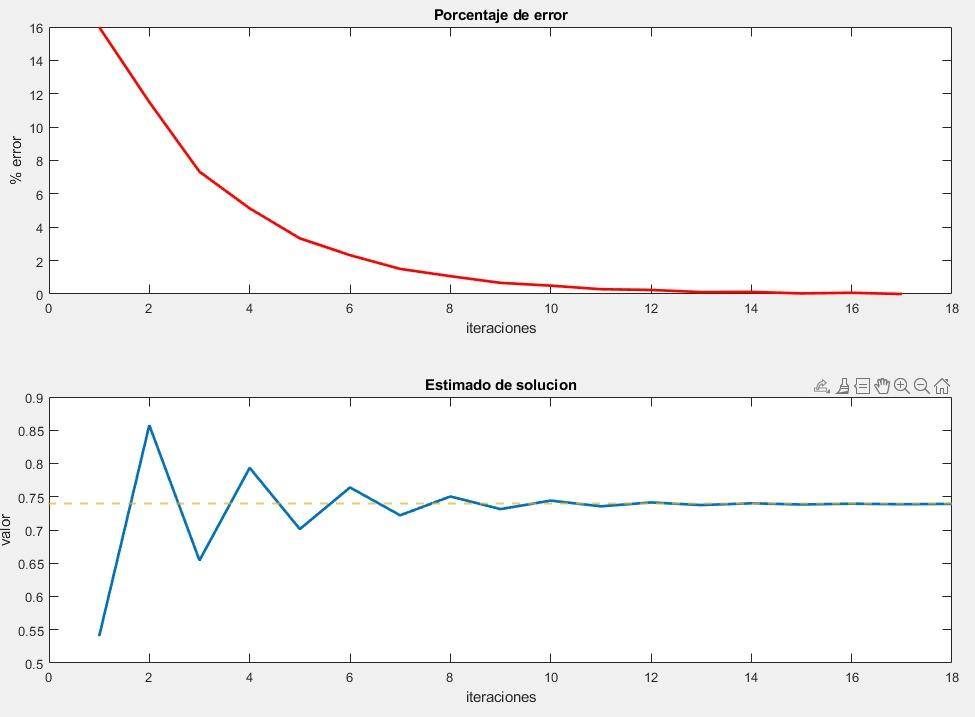

Plot for f(x)=cos(x)-x 

Output of:

f= @(x) cos(x)
fixedpoint(f,1,.1,100,1)